# Extremum Seeking Control: Mass Spring Damper System 

This work on Extremum Seeking Control (ESC) for a mass-spring-damper system includes a theoretical background, a brief example using Simulink, a mathematical model of the system, and a live script to compare controllers through simulation. It covers the system's dynamics, the use of a PI regulator to control mass position, and the application of ESC to regulate the mass position. The live script enables a comprehensive comparison of  controllers via simulation.

## **1. Theoretical Background**

 Extremum-seeking control (ESC) is a model-free, real-time adaptive control algorithm that is effective for adjusting parameters to unknown system dynamics and mapping control parameters to an objective function. Extremum-seeking can be used to tackle static optimisation problems and to optimise parameters in dynamic systems. 

This strategy becomes particularly useful when the mathematical model of the system is unknown or too complex to employ openly in control design. In general, the extremum-seeking control method consists of the following stages, as seen in the figure below:

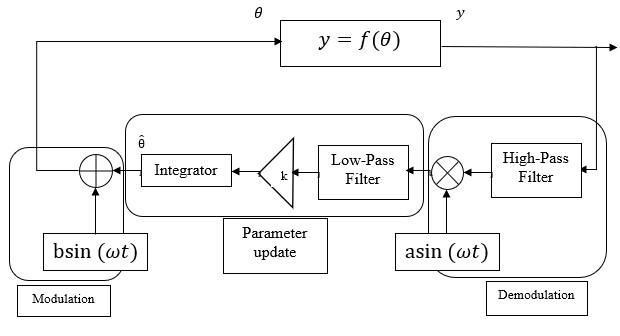

- **Modulation:** Perturb the value of the parameter being optimized using a low-amplitude sinusoidal signal. 

- **System Response: **The system being optimized reacts to the parameter perturbations. This reaction causes a corresponding change in the objective function value. 

- **Demodulation**: Multiply the objective function signal by a sinusoid with the same frequency as the modulation signal. This stage includes an optional high-pass filter to remove bias from the objective function signal. 

- **Parameter Update**: Update the parameter value by integrating the demodulated signal. The parameter value corresponds to the state of the integrator. This stage includes an optional low-pass filter to remove high-frequency noise from the demodulated signal.

Extremum-seeking control (ESC) consists of several critical steps for the continuous change of control parameters and the improvement of system performance. The procedure entails defining an objective function, introducing controlled disturbances, analysing system reactions, estimating objective function gradients, modifying parameters appropriately, and iterating through these processes in real-time. To ensure optimal system states, a convergence check is designed that considers stability and application-specific tweaking. The method is meant to adapt to changes in system dynamics while maintaining efficiency in the face of uncertainty. Following this methodical approach allows ESC to optimise system performance in the absence of a specified model.

To reach more deatiled extremum seeking control approach information, please visit the following links:

[MathWorks Explanation](https://www.mathworks.com/help/slcontrol/ug/extremum-seeking-control.html)

[A book about ESC](https://link.springer.com/book/10.1007/978-1-4471-2224-1)

## 2. A Brief Example about ESC on Simulink

First of all, to start with a comprehensive brief example on ESC application, the following system has been created:

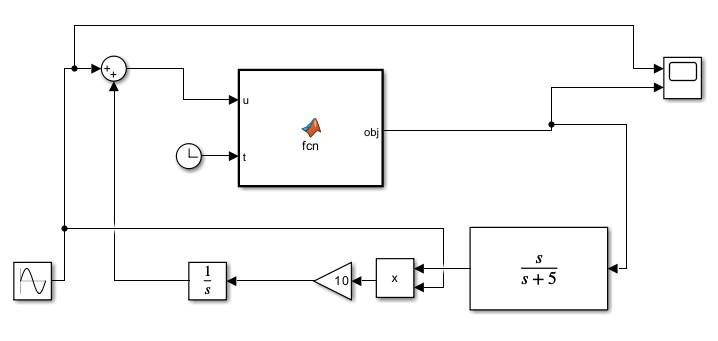

We discuss a sine wave signal with an amplitude of 0.3 units and a frequency of 30 rad/sec used in both modulation and demodulation stages. The modulation process combines this sine wave with the control signal, while demodulation separates it to extract the system's response. A sinusoidal reference signal with a frequency significantly lower than the system's dynamic range is recommended to capture slow variations accurately. Demodulation typically uses a low-pass filter to isolate low-frequency components. In this application, the sine wave parameters remain consistent, and an integrator in the ESC system corrects steady-state errors. A High-Pass Filter (HPF) in ESC filters out low-frequency components, allowing the control system to focus on higher frequency variations. The HPF transfer function can be determined using a transfer function block in Simulink.

syms s
numerator1=[1 0];
denumerator1=[1 5];
TFLP=tf(numerator1,denumerator1)

TFLP =
 
    s
  -----
  s + 5
 
Continuous-time transfer function.
Model Properties


As already mentioned, now the objective function can be defined. The function block of Simulink model has the following code to specify the objective function


$$
 obj = fcn(u,t)\\
    obj = 20 - (0.2 \cdot (10 - 0.1 \cdot t - u)^2);
$$


Here $t$ identifies the time series and $u$ stands for input of the block. The main goal is reaching 20 units within modulation and demodulation, so ESC. The system output can be seen through following code block:

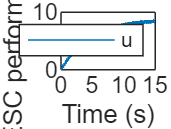

 sim genericexample;
 figure (1); plot(t,U);
 legend('u');
 xlabel('Time (s)'); ylabel(' ESC performance '); 

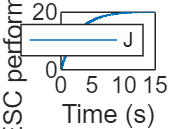

  figure (2); plot(t,J);
  legend('J');
  xlabel('Time (s)'); ylabel(' ESC performance '); 

## 3. Mathematical Model of the Mass-Spring-Damper System

A mass-spring-damper system is a common mechanical system used in physics and engineering to model the behavior of a mass (m) attached to a spring (with spring constant k) and a damper (with damping coefficient c). This system is often employed to study the dynamics of vibrational and oscillatory motion. The system can be seen as the following figure:

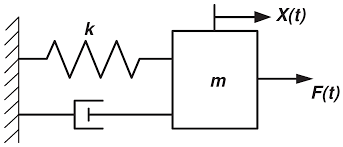

The equation of motion for the mass-spring-damper system can be expressed as:


$$m\ddot{x} +\mathrm{kx}+c\dot{x} =F$$


To apply the transfer function on this system, Laplace transform can be operated as it follows:


$$\begin{array}{l}
m\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x+c\frac{\mathrm{d}}{\mathrm{d}t}x+kx=F\\
\mathrm{Laplace}\;\mathrm{Transform}\\
\left(m\cdot s^2 +c\cdot s+k\;\right)X\left(s\right)=F\left(s\right)
\end{array}$$


This model has been applied on Simulink and the block diagram of the model is programmed as follows:

### 3.1 Dynamics

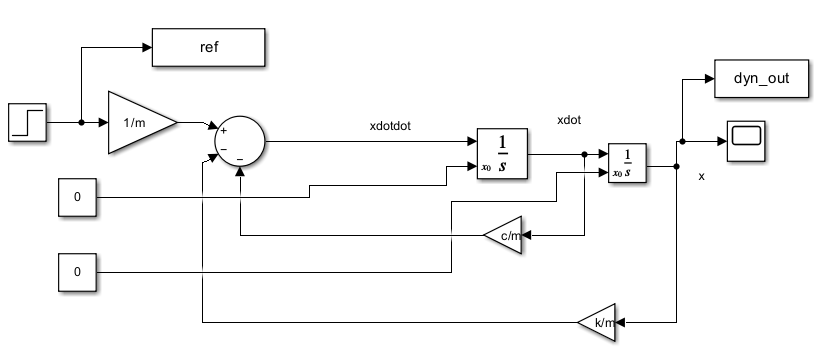

The system was subjected to a step input in the form of a force applied to the mass. This force was utilized to displace the mass, guiding it to a predetermined position, and allowing the system to reach a stable, steady state.

### **3.2 A PI regulator to control the mass position**

Moreover, Simulink PID block as shown in the picture has been inserted into the system block diagram and then according to automatic PI tunner application of MATLAB, P and I  gains have been tunned as:

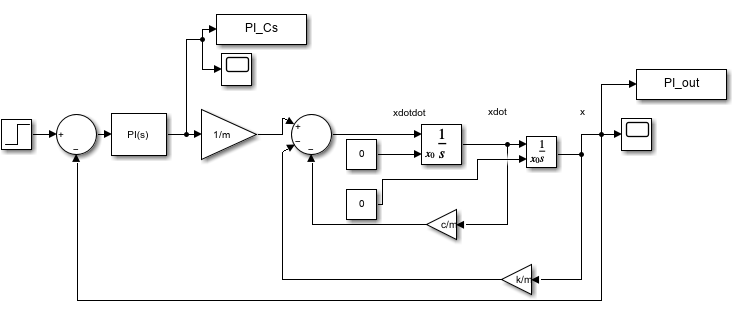

The PI controller has to generate the force input shapes that cancel the vibration and keep the mass position m=1 metre.

### 3.3 Extremum Seeking Control ESC regulates** the mass position**

Finally, extremum seeking control schematic is applied and the general frame of the system with ESC can be seen on the following figure:

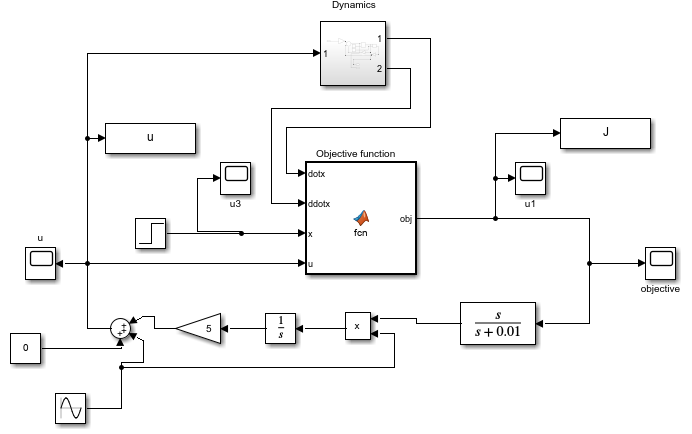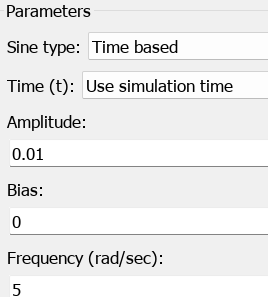

The main idea is to use an objective function that will generate u as the force paterns required to cancel the vibration and keep the mass position m=1 metre. 

Using the equation of motion and making $u$=F,

$m\ddot{x} +\mathrm{kx}+c\dot{x} =u$   we generate the objective function as follows:


$$\mathrm{obj}=\mathrm{fcn}\left(u,\ddot{x} ,\dot{x} ,x\right)$$



$$\mathrm{obj}=\left(x-\frac{\left(u-c\dot{x} -m\ddot{x} \right)}{k}\right)$$


To visualize the model outputs for each scheme, the following initial simulation and system parameters are stated:  

Simulation Parameters

  clc;clear all;
  h=0.001;
  Ref_in=1;

 System Parameters 

  m=2;
  c=0.5;
  k=1;

Plot response

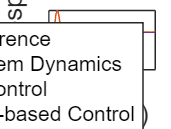

   sim exampleMSDs;
  figure (1); plot(t,ref,t,dyn_out,t,PI_out,t,J);
  legend('Reference', 'System Dynamics','PI Control','ESC-based Control');
  xlabel('Time (s)'); ylabel('Input-output response (m)'); 

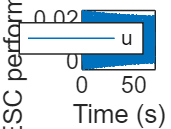

  figure(2); plot(t,u);
  legend('u');
  xlabel('Time (s)'); ylabel(' ESC performance '); 

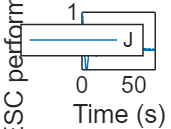

  figure (3); 
  plot(t,J);
  legend('J');
  xlabel('Time (s)'); ylabel(' ESC performance '); 

The ESC performs excellently in generating the force required to negate the system vibration. However, there is still a minor steady-state error. The controller causes an abrupt change in the transient response. There are still some evaluation about the amount of effort required to achieve the control requirements. 

It is a work by